# Assignment: EPO4, Module 1, Machine learning

***Important Note:*** *Dear students, Here, in this live script, we have tried to guid you through the steps you need to take to complete the first assignment. We have included part of the code for you and you need to complete the rest denoted by "% your code here ". You should first uncomment those and then complete them.. This file is just to help you, feel free to change any line of code or use other functions, as long as it's correct and provides the expected results. Working in a live script is very similar to a normal script. The text will be treated as comment. When you are done, you can export this live script as Word or LaTeX and add it as an appendix to your midterm report for module 1.  You can also use the figures in the main part of your midterm report. If a function is new for you type "doc function_name" in the command window to see the its detail and examples. *

## 3.4 Assignment

There are many data repositories online that are typically used to benchmark machine learning algorithms. One of them is the [UC Irvine Machine Learning Repository](http://archive.ics.uci.edu/ml/index.php). It maintains 497 datasets that can be used for different learning tasks like regression and classification. In this module, you will use the Parkinson Speech Dataset with multiple types of sound recordings. This dataset consists of two subsets of data. Here, you will only use the set called “Train Data”. We already prepared it for you and you can download it from Brightspace. The file is called Data_UCI_EPO4.mat.

## 3.4.1 Lab tasks

This dataset consists of 40 subjects, 20 patients suffering from Parkinson’s disease (Patients in the dataset), and 20 healthy volunteers (Controls in the dataset). For these assignments, it is not relevant to consider the patients separately from the controls. This information can be ignored, but it is mentioned here for completeness.

Each subject was asked to produce the following sounds:

- Sustained vowel a

- Sustained vowel o

- Sustained vowel u

- Numbers from 1 to 10 (N1-N10 in the dataset)

- 10 different words (Word1 - Word10 in the dataset)

Each sound is characterized by 25 different features that are included in the dataset as a matrix of 40*25.

To find out how these features were extracted, check the following paper, available in Brightspace:

Erdogdu Sakar B., Isenkul M., Sakar C.O., Sertbas A., Gurgen F., Delil S., Apaydin H., Kursun O., “Collection and Analysis of a Parkinson Speech Dataset with Multiple Types of Sound Recordings”,IEEE Journal of Biomedical and Health Informatics, vol. 17(4), pp. 828-834, 2013.

The dataset contains the Subject_Label, which indicates whether the subject is a patient or a control. For the assignments, this label information should not be relevant for the problem you need to solve. In fact, the classification should work for both control and patient data. (Optional) It might be that the performance is lower for patient data. Keep this in mind when evaluating the performance of your algorithm. For instance, you could split both groups and evaluate the performance separately.

For your midterm report, you need to justify every step in the design, for both assignments separately. Start from the separation of training and test set, your validation scheme, the classifier that you select, and the performance evaluation. Remember to always report the performance on an independent test set. 

## Task 1: Words vs. vowels classification 

The first task is to design a binary classifier to discriminate between one word and one vowel of your choice. Here you can use as a word any number if you find that it can be better distinghuish from a vowel. Ideally, you should be able to separate any vowel from any word, but if you find that one particular word or number leads to the best performance, go ahead and use it but always justify your selection. This will help you in module 2, when selecting your dictionary of commands. You can do this by selecting pairs at the time. For example, N1 and the vowel a first, then other pair and so on. You could, for example, classify between a and all the words, one word at the time, and select which word leads to the best performance. Remember, for this assignment you do not need to select all the words at once, since here you are dealing with a binary problem.

### Load Data

Let's load the dataset. You first need to download the data from Brightspace and put in in the same directory as this live script.

%% Load dataset
load Data_UCI_EPO4.mat;

As you can see in the workspace, we have a matrix for each vowel, word or number. The matrices contain 40 samples and 25 features. 

The first step is to make our training and test data. For this task, and for now, we decide to classify vowel "A" from word 1 "Word1". We should put the matrices for these tow classes in one data matrix to form the complete data matrix. The data matrix will then be of size 80 (samples) by 25 (features).

sel1= A;
sel2= Word1;

% Data matrix for the selected words/vowels/numbers
X = [sel1;sel2]; 

now we should make the output labels, a 80*1 vector. We assign vowel "A" to class 1 and word 1 to class 2.

Y = [ones(40,1);2*ones(40,1)]; 

### Train-test Split

Let's split the data into two sets, the training set (70%) for training the classifier model and test set  (30%) for testing the moldel. We will do this in several steps: first we loop through all the classes, for each class we first find the indices of data samples belonging to that class and then shuffle them for a nice mix, next we use the first 70% of the samples for training and the rest for test.

percent_train_split=70/100;
train_id=[];
test_id=[];
num_classes=length(unique(Y)); 

% loop through the classes
for i=1:num_classes 
    % % finding the indices belonging to each class: use find()
    ind_i = find(Y==i);
    
    % %shuffling the indice
    ind_i_perm=ind_i(randperm(length(ind_i)));
    
    % % the split point for train test
    ind_split= percent_train_split * length(ind_i_perm);
    
    % % adding the train ids to the the previous ids 
    train_id= [train_id; ind_i_perm(1:ind_split)];
    
    % % adding the test ids to the the previous ids 
    test_id= [test_id; ind_i_perm(ind_split+1:length(ind_i_perm))]; 
    
end

### Splitting the data

You can use the train and test ids (for rows!) to split the train and test data

% % splitting the inputs
% complete the codes below
Xtrain= X(train_id,1:25);
Xtest= X(test_id,1:25);

% % splitting the labels
Ytrain= Y(train_id,1);
Ytest= Y(test_id,1);

### Standard Normalization

Next we should performing standard normalization on train data and finding the save its mean and standard deviation, use "zscore()" function here.

[Xtrain,mu_train,sigma_train] = zscore(Xtrain);

we should perform any changes we make on training data on the test data too. using the mean and standard deviation of the training data to the test data too

Xtest= (Xtest-mu_train)./sigma_train;

### Feature Selection using mRMR

Here we will use a feature selection method  called Minimum Redundancy Maximum Relevance (mRMR). As you can already imagine, this methodology finds the most relevant features, while minimizing their redundancy. This methodology is based on formulations of mutual information between the features and the targets y. For now, we will not dig into the theory behind this approach but if you are interested, you can read the paper by C. Ding and H. Peng, entitled “Minimum Redundancy Feature Selection from Microarray Gene Expression Data” that you can find on Brightspace.

In this module, you can use the Matlab function "fscmrmr()" for this part:

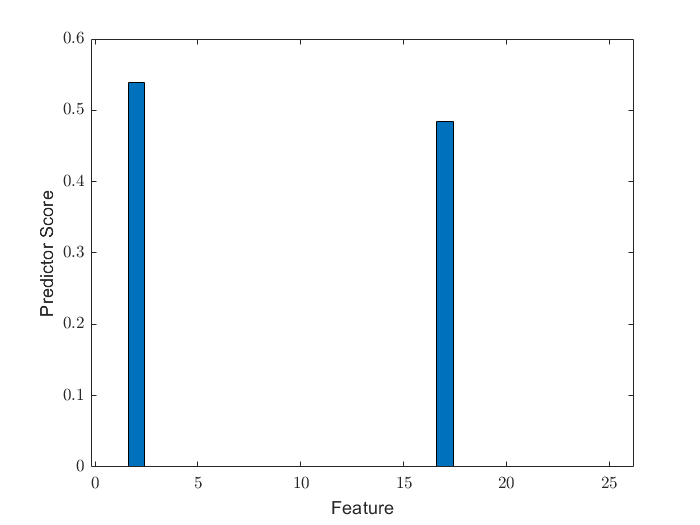

[idx,scores] = fscmrmr(Xtrain,Ytrain);
bar(idx,scores(idx))% Create bar graph
xlabel('Feature')
set(gca,'TickLabelInterpreter','latex');
ylabel('Predictor Score'); hold off;

you can select the features with higher importance for the rest of this assignment but for now we will just keep all the features.

### Training

We'll now train a random forest classifier for classification of these two classes. You can do this in MATLAB using "TreeBagger()" function. let's use 20 trees and don't forget to set 'Method' to 'classification'.

% This makes sure we get the same results every time we run the code.
rng default

% How many trees do you want in the forest? 
nTrees = 20;
 
% Train the TreeBagger (Random Forest).
model = TreeBagger( nTrees,Xtrain,Ytrain ...
    , 'Method', 'classification');

you can try random forests with various number of trees or set other variables like "model = TreeBagger(nTrees,Xtrain,Ytrain ..., 'Method', 'classification','InBagFraction',0.5,'MaxNumSplits',5);" for better performance. 

### Testing the model on test data

First use model.predict() to predict the output values for test data. and then use "str2double" to turn them into doubles.

Ytest_pred_str = model.predict(Xtest);
Ytest_pred =  str2double(Ytest_pred_str);

### Turn the numerical outputs to categorial

To make the confusion matrix, we first need to replace the current numerical labels by categorical variables. You can do this by first creating matrices filles with zeros of size: number of samples by number of classes. Next for both true output and predicted output we loop through the classes and for each we set the correponding row and the columns with those outputs equal to one.

Ytest_cat= zeros(num_classes,length(Ytest));
Ytest_pred_cat= zeros(num_classes,length(Ytest_pred));

for i=1:num_classes
    Ytest_cat(i, Ytest==i) = 1;
    Ytest_pred_cat(i, Ytest_pred==i) = 1;
end

### Plot confusion matrix

you can use the "plotconfusion()" function to plot the confusion matrix. Note that the confusion matrix is sufficient for this task but if you are interested you can also calculate the performance metrics:Sensitivity, Specificity, and Accuracy.

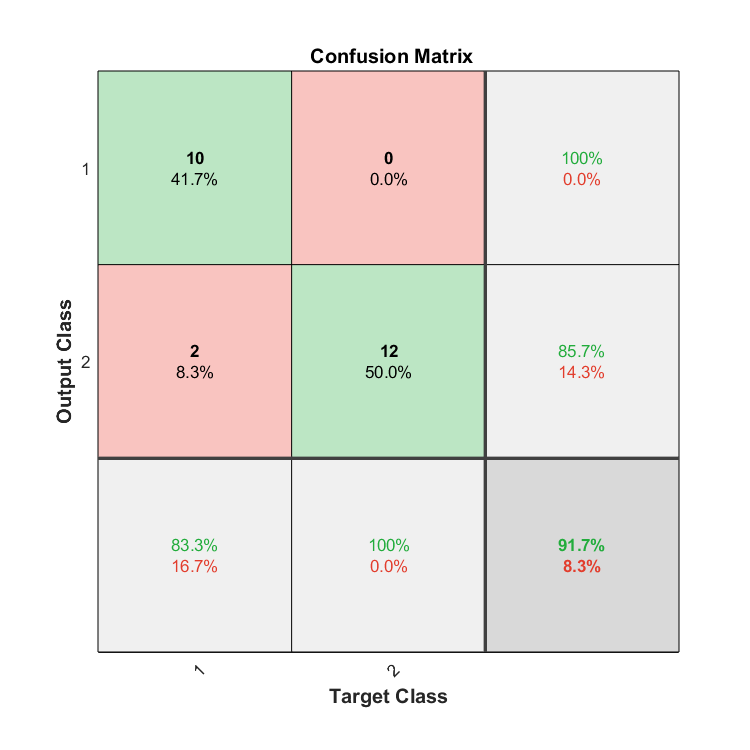

plotconfusion(Ytest_cat, Ytest_pred_cat);


%For loop of task 1

Error using vertcat
Dimensions of arrays being concatenated are not consistent.


for i=1:3
    if (i == 1)
        sel1 = A;
    elseif (i == 2)
        sel1 = O;
    elseif (i == 3)
        sel1 = U;
    end
    for j=1:9
        switch j
            case 1
                sel2 = Word1;
            case 2
                sel2 = Word2;
            case 3
                sel2 = Word3;
            case 4
                sel2 = Word4;
            case 5
                sel2 = Word5;
            case 6
                sel2 = Word6;
            case 7
                sel2 = Word7;
            case 8
                sel2 = Word8;
            case 9
                sel2 = Word9;
        end
        
        % Data matrix for the selected words/vowels/numbers
X = [sel1;sel2]; 
Y = [ones(40,1);2*ones(40,1)]; 

percent_train_split=70/100;
train_id=[];
test_id=[];
num_classes=length(unique(Y)); 

% loop through the classes
for i=1:num_classes 
    % % finding the indices belonging to each class: use find()
    ind_i = find(Y==i);
    
    % %shuffling the indice
    ind_i_perm=ind_i(randperm(length(ind_i)));
    
    % % the split point for train test
    ind_split= percent_train_split * length(ind_i_perm);
    
    % % adding the train ids to the the previous ids 
    train_id= [train_id; ind_i_perm(1:ind_split)];
    
    % % adding the test ids to the the previous ids 
    test_id= [test_id; ind_i_perm(ind_split+1:length(ind_i_perm))]; 
    
    % % splitting the inputs
    % complete the codes below
    Xtrain= X(train_id,1:25);
    Xtest= X(test_id,1:25);

    % % splitting the labels
    Ytrain= Y(train_id,1);
    Ytest= Y(test_id,1);
    
    [Xtrain,mu_train,sigma_train] = zscore(Xtrain);
    
    Xtest= (Xtest-mu_train)./sigma_train;
    
    subplot(3,9,i+j)
    [idx,scores] = fscmrmr(Xtrain,Ytrain);
    bar(idx,scores(idx))% Create bar graph
    xlabel('Feature')
    set(gca,'TickLabelInterpreter','latex');
    ylabel('Predictor Score'); hold on;
    
end
        
    end
end

you can repeat this task for different combination of words and vowels or make a for loop to do it automatically but don't forget to report which word and vowel provided the best results.